## initialize environment

defaultDir = 'M:\Projects and Analysis\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 7 - P2ry1 KO in vivo');

%%example images
list = loadFileList('.\Data\P2ry1 KO\*\meantif_short.tif');
cax = [0 250];
for i=1:size(list,1)
    img = loadTif(list{i},16);
    figure;
    imshow(img);
    colormap(gfb);
    caxis(cax)
end
'WT'

ans = 'WT'

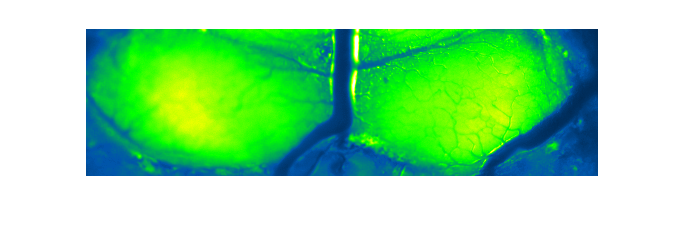

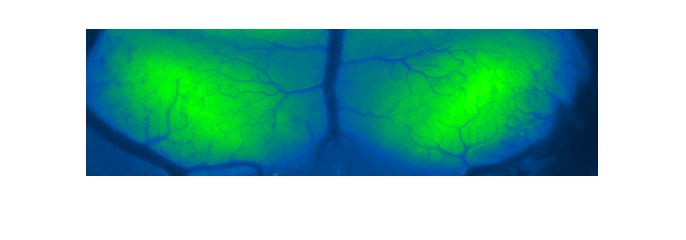

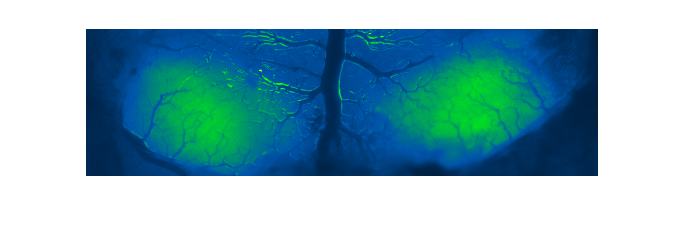

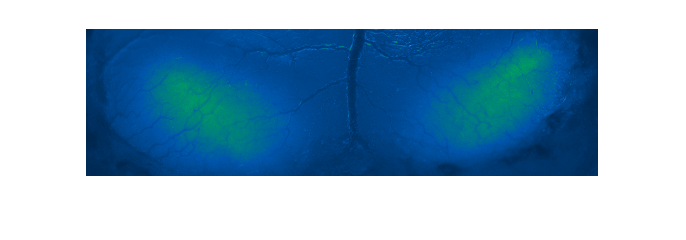

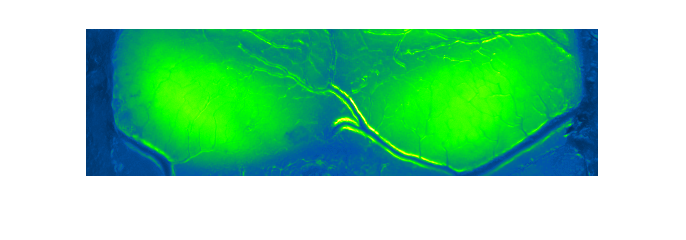

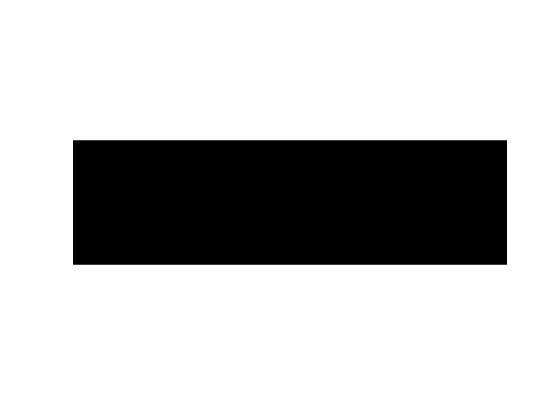

list = loadFileList('.\Data\WT\*\meantif_short.tif');
for i=1:size(list,1)
    img = loadTif(list{i},16);
    figure;
    imshow(img);
    colormap(gfb);
    caxis(cax)
end

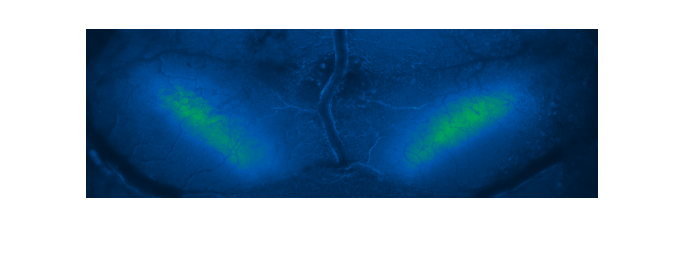

%final
cax = [0 250];

list = loadFileList('.\Data\WT\*\meantif_short.tif');
img = loadTif(list{3},16);
figure;
imshow(img);
truesize;
colormap(gfb);
caxis(cax)
figQuality(gcf,gca,[3,2])
truesize;
export_fig('.\EPS Panels\WT_average.eps','-eps');

list = loadFileList('.\Data\P2ry1 KO\*\*\meantif_short.tif');
img = loadTif(list{3},16);
figure;
imshow(img);
truesize;
colormap(gfb);
caxis(cax)
export_fig('.\EPS Panels\KO_average.eps','-eps')


list = loadFileList('.\Data\P2ry1 KO\*\ICmovs*.mat');
analGroupData(list,1)

list = loadFileList('.\Data\P2ry1 KO\*\ICinfo*.mat');
load(list{3})
[stats, pkData, h, h1] = P2ry1_findICpeaksdFoF(ICsignal,filePath,'dFoF',1);
figure(h);
xlim([-.5 .5])

export_fig('.\EPS Panels\P2ry1_exLolli.eps','-eps');
figure(h1);
export_fig('.\EPS Panels\P2ry1_histo.eps','-eps');


list = loadFileList('.\Data\WT\*\ICinfo*.mat');
load(list{3})
[stats, pkData, h2, h3] = P2ry1_findICpeaksdFoF(ICsignal,filePath,'dFoF',1);

h1 =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1.8000 1.2000]
       Units: 'inches'

  Show all properties


Rdom = 73

tempPkData = 	1.0e+03 *

    0.0630    0.0002    0.0630    0.0001    0.0001    0.0020    0.0010
    0.0750    0.0002    0.0750    0.0001    0.0001    0.0020    0.0010
    0.2290    0.0001    0.2310    0.0001    0.0001    0.0010    0.0010
    0.2580    0.0001    0.2550    0.0001    0.0000    0.0010    0.0010
    0.2940    0.0000    0.2940    0.0000    0.0000    0.0020    0.0010
    0.3570    0.0001    0.3570    0.0000    0.0001    0.0020    0.0010
    0.4050    0.0001    0.4040    0.0001    0.0000    0.0010    0.0010
    0.4820    0.0002    0.4760    0.0001    0.0000    0.0010    0.0010
    0.5220    0.0004    0.5240    0.0002    0.0001    0.0010    0.0010
    0.7210    0.0001    0.7210    0.0000    0.0001    0.0020    0.0010


LIC: 114 peaks total, 65 corresponding RIC peaks.
RIC: 102 peaks total, 65 corresponding LIC peaks.
Mean RIC amplitude: 0.097155
Mean LIC amplitude: 0.095977
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-330\ICinfo16_dFoF


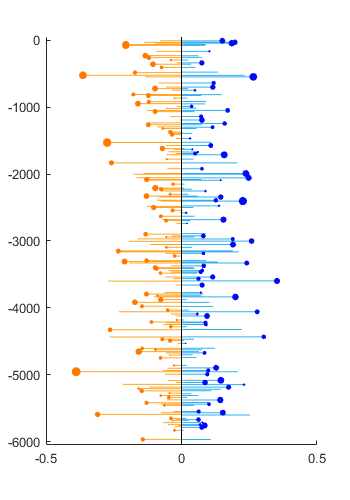

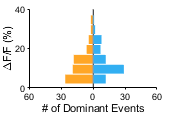

figure(h2);
xlim([-.5 .5])
export_fig('.\EPS Panels\WT_exLolli.eps','-eps');
figure(h3);
print('.\EPS Panels\WT_histo.pdf','-dpdf')
export_fig('.\EPS Panels\WT_histo.eps','-eps');

binLim =          0    0.0200    0.0700    0.1200    0.1700    0.2200    0.2700    0.3200  100.0000


M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-338\ICinfo16_dFoF.mat


Rdom = 55

tempPkData = 	1.0e+03 *

    0.4210    0.0001    0.4210    0.0000    0.0000    0.0020    0.0010
    0.4700    0.0001    0.4690    0.0001    0.0000    0.0010    0.0010
    0.6130    0.0001    0.6130    0.0001    0.0001    0.0020    0.0010
    0.7120    0.0001    0.7120    0.0000    0.0001    0.0020    0.0010
    0.7350    0.0001    0.7350    0.0000    0.0001    0.0020    0.0010
    0.7780    0.0000    0.7780    0.0000    0.0000    0.0020    0.0010
    0.8180    0.0001    0.8130    0.0000    0.0000    0.0010    0.0010
    0.8540    0.0001    0.8570    0.0001    0.0000    0.0010    0.0010
    0.9840    0.0002    0.9830    0.0002    0.0000    0.0010    0.0010
    1.1080    0.0002    1.1080    0.0001    0.0001    0.0020    0.0010


LIC: 81 peaks total, 43 corresponding RIC peaks.
RIC: 80 peaks total, 43 corresponding LIC peaks.
Mean RIC amplitude: 0.070487
Mean LIC amplitude: 0.083963
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-338\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-344\ICinfo16_dFoF.mat


Rdom = 36

tempPkData = 	1.0e+03 *

    0.0670    0.0000    0.0670    0.0000    0.0000    0.0020    0.0010
    0.1850    0.0001    0.1850    0.0001    0.0001    0.0020    0.0010
    0.2670    0.0002    0.2700    0.0001    0.0001    0.0010    0.0010
    0.2980    0.0001    0.2980    0.0001    0.0000    0.0030    0.0010
    0.3110    0.0001    0.3110    0.0000    0.0001    0.0020    0.0010
    0.3460    0.0002    0.3460    0.0001    0.0002    0.0020    0.0010
    0.3560    0.0002    0.3560    0.0001    0.0001    0.0020    0.0010
    0.5660    0.0001    0.5660    0.0000    0.0000    0.0020    0.0010
    0.6590    0.0000    0.6590    0.0000    0.0000    0.0020    0.0010
    0.8260    0.0001    0.8260    0.0000    0.0001    0.0020    0.0010


LIC: 51 peaks total, 17 corresponding RIC peaks.
RIC: 45 peaks total, 17 corresponding LIC peaks.
Mean RIC amplitude: 0.049704
Mean LIC amplitude: 0.057825
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-344\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-354\ICinfo16_dFoF.mat


Rdom = 57

tempPkData = 	1.0e+03 *

    0.0900    0.0002    0.0900    0.0001    0.0001    0.0020    0.0010
    0.1160    0.0002    0.1160    0.0000    0.0002    0.0020    0.0010
    0.2150    0.0004    0.2180    0.0002    0.0002    0.0010    0.0010
    0.2390    0.0006    0.2450    0.0005    0.0001    0.0010    0.0010
    0.5850    0.0003    0.5840    0.0002    0.0001    0.0010    0.0010
    0.6310    0.0006    0.6290    0.0002    0.0004    0.0010    0.0010
    0.8100    0.0001    0.8100    0.0000    0.0001    0.0020    0.0010
    0.9540    0.0004    0.9540    0.0003    0.0000    0.0030    0.0010
    0.9690    0.0006    0.9690    0.0002    0.0003    0.0020    0.0010
    0.9920    0.0003    0.9920    0.0001    0.0002    0.0030    0.0010


LIC: 73 peaks total, 46 corresponding RIC peaks.
RIC: 81 peaks total, 46 corresponding LIC peaks.
Mean RIC amplitude: 0.12608
Mean LIC amplitude: 0.13065
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-354\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-360\ICinfo16_dFoF.mat


Rdom = 49

tempPkData = 	1.0e+03 *

    0.0850    0.0001    0.0790    0.0000    0.0001    0.0010    0.0010
    0.2440    0.0001    0.2440    0.0000    0.0000    0.0020    0.0010
    0.3650    0.0000    0.3650    0.0000    0.0000    0.0020    0.0010
    0.4370    0.0004    0.4370    0.0002    0.0001    0.0010    0.0010
    0.5700    0.0000    0.5700    0.0000    0.0000    0.0020    0.0010
    0.6450    0.0001    0.6450    0.0000    0.0001    0.0020    0.0010
    0.7130    0.0001    0.7140    0.0000    0.0001    0.0010    0.0010
    0.8420    0.0000    0.8420    0.0000    0.0000    0.0020    0.0010
    1.0080    0.0002    1.0080    0.0001    0.0000    0.0020    0.0010
    1.1750    0.0000    1.1750    0.0000    0.0000    0.0020    0.0010


LIC: 57 peaks total, 28 corresponding RIC peaks.
RIC: 65 peaks total, 28 corresponding LIC peaks.
Mean RIC amplitude: 0.070177
Mean LIC amplitude: 0.062635
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-360\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-361\ICinfo16_dFoF.mat


Rdom = 52

tempPkData = 	1.0e+03 *

    0.1290    0.0006    0.1390    0.0005    0.0001    0.0010    0.0010
    0.2090    0.0001    0.2090   -0.0000    0.0001    0.0020    0.0010
    0.2350    0.0000    0.2350    0.0000    0.0000    0.0030    0.0010
    0.2560    0.0001    0.2560    0.0000    0.0000    0.0020    0.0010
    0.2900    0.0001    0.2900    0.0000    0.0001    0.0020    0.0010
    0.4400    0.0001    0.4400    0.0000    0.0000    0.0020    0.0010
    0.4680    0.0001    0.4680    0.0000    0.0000    0.0020    0.0010
    0.5120    0.0004    0.5110    0.0002    0.0002    0.0010    0.0010
    0.5320    0.0004    0.5340    0.0002    0.0002    0.0010    0.0010
    0.7460    0.0004    0.7440    0.0002    0.0002    0.0010    0.0010


LIC: 52 peaks total, 26 corresponding RIC peaks.
RIC: 66 peaks total, 26 corresponding LIC peaks.
Mean RIC amplitude: 0.082704
Mean LIC amplitude: 0.074333
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-361\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-591\ICinfo16_dFoF.mat


Rdom = 63

tempPkData = 	1.0e+03 *

    0.0460    0.0002    0.0540    0.0001    0.0001    0.0010    0.0010
    0.0900    0.0001    0.0930    0.0001    0.0000    0.0010    0.0010
    0.3340    0.0001    0.3320    0.0000    0.0001    0.0010    0.0010
    0.3900    0.0002    0.3900    0.0002    0.0000    0.0020    0.0010
    0.4030    0.0003    0.4030    0.0001    0.0002    0.0020    0.0010
    0.6130    0.0001    0.6100    0.0000    0.0000    0.0010    0.0010
    0.6540    0.0001    0.6540    0.0000    0.0000    0.0020    0.0010
    0.7120    0.0001    0.7120    0.0000    0.0001    0.0010    0.0010
    1.3130    0.0000    1.3130    0.0000    0.0000    0.0020    0.0010
    1.4010    0.0000    1.4010   -0.0000    0.0000    0.0020    0.0010


LIC: 86 peaks total, 54 corresponding RIC peaks.
RIC: 81 peaks total, 54 corresponding LIC peaks.
Mean RIC amplitude: 0.11074
Mean LIC amplitude: 0.099206
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-591\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-805\ICinfo16_dFoF.mat


Rdom = 47

tempPkData = 	1.0e+03 *

    0.3180    0.0004    0.3170    0.0001    0.0003    0.0010    0.0010
    0.6390    0.0000    0.6400    0.0000    0.0000    0.0010    0.0010
    0.7270    0.0000    0.7270    0.0000    0.0000    0.0020    0.0010
    0.9090    0.0000    0.9090    0.0000    0.0000    0.0020    0.0010
    1.0400    0.0002    1.0450    0.0001    0.0000    0.0010    0.0010
    1.4070    0.0001    1.4070    0.0000    0.0001    0.0010    0.0010
    1.4830    0.0000    1.4830    0.0000    0.0000    0.0020    0.0010
    1.8860    0.0000    1.8960    0.0000    0.0000    0.0010    0.0010
    2.1330    0.0004    2.1300    0.0001    0.0002    0.0010    0.0010
    2.4000    0.0001    2.4000    0.0000    0.0001    0.0020    0.0010


LIC: 48 peaks total, 32 corresponding RIC peaks.
RIC: 65 peaks total, 32 corresponding LIC peaks.
Mean RIC amplitude: 0.11951
Mean LIC amplitude: 0.10182
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\P2ry1 KO\Experiment-805\ICinfo16_dFoF


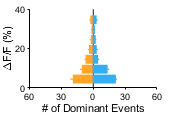

%groupData
list = loadFileList('.\Data\P2ry1 KO\*\ICinfo*.mat');
KO_stat = groupData_broad(list,16);

binLim =          0    0.0200    0.0700    0.1200    0.1700    0.2200    0.2700    0.3200  100.0000


M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-265\ICinfo16_dFoF.mat


Rdom = 53

tempPkData = 	1.0e+03 *

    0.0120    0.0001    0.0120    0.0000    0.0000    0.0020    0.0010
    0.0520    0.0001    0.0600    0.0001    0.0000    0.0010    0.0010
    0.4570    0.0000    0.4570    0.0000    0.0000    0.0020    0.0010
    0.4850    0.0002    0.4850    0.0002    0.0000    0.0010    0.0010
    0.5690    0.0000    0.5690    0.0000    0.0000    0.0020    0.0010
    0.6160    0.0002    0.6120    0.0001    0.0000    0.0010    0.0010
    0.8020    0.0001    0.8020    0.0000    0.0000    0.0010    0.0010
    0.8510    0.0000    0.8510    0.0000    0.0000    0.0020    0.0010
    0.9130    0.0000    0.9130    0.0000    0.0000    0.0020    0.0010
    1.2560    0.0000    1.2560    0.0000    0.0000    0.0020    0.0010


LIC: 67 peaks total, 48 corresponding RIC peaks.
RIC: 69 peaks total, 48 corresponding LIC peaks.
Mean RIC amplitude: 0.056401
Mean LIC amplitude: 0.048531
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-265\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-314\ICinfo16_dFoF.mat


Rdom = 71

tempPkData = 	1.0e+03 *

    0.0100    0.0001    0.0070    0.0001    0.0000    0.0010    0.0010
    0.0370    0.0001    0.0330    0.0001    0.0000    0.0010    0.0010
    0.0620    0.0001    0.0680    0.0000    0.0000    0.0010    0.0010
    0.1120    0.0000    0.1120    0.0000    0.0000    0.0020    0.0010
    0.1570    0.0001    0.1560    0.0001    0.0000    0.0010    0.0010
    0.2160    0.0003    0.2150    0.0002    0.0001    0.0010    0.0010
    0.2420    0.0002    0.2420    0.0001    0.0000    0.0020    0.0010
    0.3060    0.0001    0.3060    0.0000    0.0000    0.0020    0.0010
    0.4790    0.0002    0.4720    0.0002    0.0000    0.0010    0.0010
    0.7800    0.0002    0.7800    0.0001    0.0000    0.0010    0.0010


LIC: 111 peaks total, 76 corresponding RIC peaks.
RIC: 114 peaks total, 76 corresponding LIC peaks.
Mean RIC amplitude: 0.11143
Mean LIC amplitude: 0.11492
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-314\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-330\ICinfo16_dFoF.mat


Rdom = 73

tempPkData = 	1.0e+03 *

    0.0630    0.0002    0.0630    0.0001    0.0001    0.0020    0.0010
    0.0750    0.0002    0.0750    0.0001    0.0001    0.0020    0.0010
    0.2290    0.0001    0.2310    0.0001    0.0001    0.0010    0.0010
    0.2580    0.0001    0.2550    0.0001    0.0000    0.0010    0.0010
    0.2940    0.0000    0.2940    0.0000    0.0000    0.0020    0.0010
    0.3570    0.0001    0.3570    0.0000    0.0001    0.0020    0.0010
    0.4050    0.0001    0.4040    0.0001    0.0000    0.0010    0.0010
    0.4820    0.0002    0.4760    0.0001    0.0000    0.0010    0.0010
    0.5220    0.0004    0.5240    0.0002    0.0001    0.0010    0.0010
    0.7210    0.0001    0.7210    0.0000    0.0001    0.0020    0.0010


LIC: 114 peaks total, 65 corresponding RIC peaks.
RIC: 102 peaks total, 65 corresponding LIC peaks.
Mean RIC amplitude: 0.097155
Mean LIC amplitude: 0.095977
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-330\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-337\ICinfo16_dFoF.mat


Rdom = 90

tempPkData = 	1.0e+03 *

    0.0310    0.0001    0.0310    0.0001    0.0001    0.0020    0.0010
    0.2400    0.0001    0.2390    0.0001    0.0001    0.0010    0.0010
    0.5170    0.0001    0.5170    0.0000    0.0000    0.0020    0.0010
    0.5500    0.0002    0.5500    0.0001    0.0001    0.0010    0.0010
    0.5770    0.0001    0.5790    0.0001    0.0000    0.0010    0.0010
    0.7510    0.0001    0.7510    0.0001    0.0001    0.0020    0.0010
    0.8750    0.0002    0.8740    0.0002    0.0000    0.0010    0.0010
    0.9960    0.0000    1.0040    0.0000    0.0000    0.0010    0.0010
    1.0980    0.0000    1.0980    0.0000    0.0000    0.0020    0.0010
    1.2890    0.0002    1.2840    0.0001    0.0000    0.0010    0.0010


LIC: 104 peaks total, 75 corresponding RIC peaks.
RIC: 122 peaks total, 75 corresponding LIC peaks.
Mean RIC amplitude: 0.084056
Mean LIC amplitude: 0.077578
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-337\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-342\ICinfo16_dFoF.mat


Rdom = 60

tempPkData = 	1.0e+03 *

    0.2280    0.0001    0.2260    0.0001    0.0000    0.0010    0.0010
    0.2610    0.0003    0.2590    0.0002    0.0001    0.0010    0.0010
    0.3980    0.0001    0.3990    0.0001    0.0000    0.0010    0.0010
    0.4490    0.0000    0.4490    0.0000    0.0000    0.0020    0.0010
    0.4710    0.0001    0.4710    0.0001    0.0000    0.0030    0.0010
    0.4870    0.0001    0.4870    0.0000    0.0001    0.0020    0.0010
    0.5060    0.0000    0.5060    0.0000    0.0000    0.0020    0.0010
    0.5720    0.0001    0.5720    0.0000    0.0000    0.0010    0.0010
    0.6030    0.0001    0.6020    0.0001    0.0000    0.0010    0.0010
    0.6320    0.0002    0.6260    0.0001    0.0001    0.0010    0.0010


LIC: 96 peaks total, 68 corresponding RIC peaks.
RIC: 103 peaks total, 68 corresponding LIC peaks.
Mean RIC amplitude: 0.059321
Mean LIC amplitude: 0.060675
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-342\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-495\ICinfo16_dFoF.mat


Rdom = 79

tempPkData = 	1.0e+03 *

    0.0470    0.0001    0.0470    0.0000    0.0001    0.0020    0.0010
    0.0890    0.0001    0.0890    0.0000    0.0001    0.0020    0.0010
    0.2450    0.0001    0.2450    0.0000    0.0001    0.0020    0.0010
    0.2890    0.0002    0.2870    0.0001    0.0001    0.0010    0.0010
    0.3040    0.0001    0.3040    0.0001    0.0000    0.0030    0.0010
    0.5840    0.0002    0.5840    0.0001    0.0001    0.0020    0.0010
    0.6000    0.0001    0.6000    0.0001    0.0000    0.0020    0.0010
    0.7730    0.0001    0.7730    0.0000    0.0001    0.0020    0.0010
    0.9010    0.0000    0.9010    0.0000    0.0000    0.0020    0.0010
    0.9410    0.0000    0.9500    0.0000    0.0000    0.0010    0.0010


LIC: 113 peaks total, 69 corresponding RIC peaks.
RIC: 105 peaks total, 69 corresponding LIC peaks.
Mean RIC amplitude: 0.076648
Mean LIC amplitude: 0.074708
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-495\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-569\ICinfo16_dFoF.mat


Rdom = 77

tempPkData = 	1.0e+03 *

    0.1250    0.0001    0.1240    0.0000    0.0001    0.0010    0.0010
    0.2430    0.0002    0.2430    0.0002    0.0001    0.0020    0.0010
    0.5070    0.0000    0.5070    0.0000    0.0000    0.0020    0.0010
    0.5420    0.0002    0.5410    0.0001    0.0000    0.0010    0.0010
    0.6220    0.0001    0.6220    0.0000    0.0000    0.0010    0.0010
    0.6910    0.0000    0.6880    0.0000    0.0000    0.0010    0.0010
    0.8050    0.0001    0.8030    0.0001    0.0000    0.0010    0.0010
    0.9220    0.0001    0.9220    0.0000    0.0001    0.0020    0.0010
    1.1380    0.0002    1.1390    0.0002    0.0000    0.0010    0.0010
    1.2390    0.0001    1.2390    0.0000    0.0001    0.0020    0.0010


LIC: 111 peaks total, 83 corresponding RIC peaks.
RIC: 110 peaks total, 83 corresponding LIC peaks.
Mean RIC amplitude: 0.11196
Mean LIC amplitude: 0.10612
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-569\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-571\ICinfo16_dFoF.mat


Rdom = 64

tempPkData = 	1.0e+03 *

    0.0650    0.0001    0.0680    0.0001    0.0000    0.0010    0.0010
    0.1210    0.0001    0.1210    0.0001    0.0000    0.0010    0.0010
    0.3510    0.0001    0.3610    0.0001    0.0000    0.0010    0.0010
    0.5100    0.0001    0.5100    0.0001    0.0000    0.0020    0.0010
    0.5350    0.0001    0.5350    0.0000    0.0001    0.0020    0.0010
    0.6170    0.0001    0.6170    0.0001    0.0000    0.0020    0.0010
    0.7030    0.0001    0.7030    0.0000    0.0000    0.0020    0.0010
    0.7360    0.0001    0.7260    0.0001    0.0000    0.0010    0.0010
    0.8350    0.0001    0.8370    0.0001    0.0000    0.0010    0.0010
    0.9250    0.0001    0.9250    0.0001    0.0000    0.0010    0.0010


LIC: 107 peaks total, 71 corresponding RIC peaks.
RIC: 105 peaks total, 71 corresponding LIC peaks.
Mean RIC amplitude: 0.11218
Mean LIC amplitude: 0.11463
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-571\ICinfo16_dFoF
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-974\ICinfo16_dFoF.mat


Rdom = 60

tempPkData = 	1.0e+03 *

    0.1520    0.0001    0.1520    0.0000    0.0000    0.0020    0.0010
    0.2230    0.0001    0.2190    0.0001    0.0000    0.0010    0.0010
    0.2940    0.0001    0.2940    0.0001    0.0001    0.0020    0.0010
    0.4790    0.0000    0.4790    0.0000    0.0000    0.0020    0.0010
    0.5170    0.0001    0.5170    0.0000    0.0000    0.0020    0.0010
    0.7740    0.0000    0.7740    0.0000    0.0000    0.0020    0.0010
    0.7870    0.0000    0.7870    0.0000    0.0000    0.0030    0.0010
    0.8630    0.0001    0.8630    0.0000    0.0000    0.0020    0.0010
    0.9030    0.0001    0.8990    0.0001    0.0001    0.0010    0.0010
    1.1430    0.0002    1.1450    0.0001    0.0000    0.0010    0.0010


LIC: 78 peaks total, 44 corresponding RIC peaks.
RIC: 77 peaks total, 44 corresponding LIC peaks.
Mean RIC amplitude: 0.097748
Mean LIC amplitude: 0.086977
M:\Projects and Analysis\Papers\P2ry1\Figure 4 - In vivo\Data\WT\Experiment-974\ICinfo16_dFoF


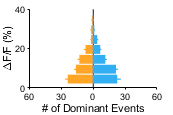

list = loadFileList('.\Data\WT\*\ICinfo*.mat');
stat = groupData_broad(list,16);

dim = [1.2 1];
markSize = [8 12];
h3 = compare2C(table2array(stat(:,11)),table2array(KO_stat(:,11)), {'WT','P2ry1 KO'}, 'Amplitude ratio', dim, markSize);

   3.0171e-06



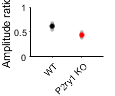

ylim([0 1]);
xtickangle(45);



h = compare2C(table2array(stat(:,7))/10,table2array(KO_stat(:,7))/10, {'WT','P2ry1 KO'}, 'Events per minute', dim, markSize);

    0.0021



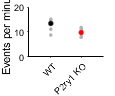

ylim([0 20]);
xtickangle(45);


h2 = compare2C(table2array(stat(:,10))/10,table2array(KO_stat(:,10))/10, {'WT','P2ry1 KO'}, 'Half-width (s)', dim, markSize);

    0.9836



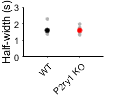

ylim([0 3]);
xtickangle(45);



h1 = compare2C(mean(table2array(stat(:,4:5)),2)*100,mean(table2array(KO_stat(:,4:5)),2)*100, {'WT','P2ry1 KO'}, 'Amplitude (% dFoF)', dim, markSize);

    0.9750



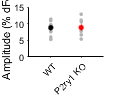

ylim([0 15]);
xtickangle(45);

mean(table2array(stat(:,7))/10)

ans = 13.4333

sterr(table2array(stat(:,7))/10,1)

ans = 0.7213

mean(table2array(KO_stat(:,7))/10)

ans = 9.7857

sterr(table2array(KO_stat(:,7))/10,1)

ans = 0.5829

[~,p] = ttest2(table2array(stat(:,7))/10,table2array(KO_stat(:,7))/10)

p = 0.0021


%ratios
mean(table2array(stat(:,11)))

ans = 0.6171

sterr(table2array(stat(:,11)),1)

ans = 0.0152

mean(table2array(KO_stat(:,11)))

ans = 0.4405

sterr(table2array(KO_stat(:,11)),1)

ans = 0.0184

list = loadFileList('.\Data\WT\*\ICinfo*.mat');
CV = [];
for i=1:size(list,1)
    load(list{i})
    [stats, pkData] = P2ry1_findICpeaksdFoF(ICsignal,filePath,'dFoF',0,0);
    temp = [pkData(:,2) pkData(:,4)];

    CV(i)=std(temp,[],1)/mean(temp,1);
end

Rdom = 53

tempPkData = 	1.0e+03 *

    0.0120    0.0001    0.0120    0.0000    0.0000    0.0020    0.0010
    0.0520    0.0001    0.0600    0.0001    0.0000    0.0010    0.0010
    0.4570    0.0000    0.4570    0.0000    0.0000    0.0020    0.0010
    0.4850    0.0002    0.4850    0.0002    0.0000    0.0010    0.0010
    0.5690    0.0000    0.5690    0.0000    0.0000    0.0020    0.0010
    0.6160    0.0002    0.6120    0.0001    0.0000    0.0010    0.0010
    0.8020    0.0001    0.8020    0.0000    0.0000    0.0010    0.0010
    0.8510    0.0000    0.8510    0.0000    0.0000    0.0020    0.0010
    0.9130    0.0000    0.9130    0.0000    0.0000    0.0020    0.0010
    1.2560    0.0000    1.2560    0.0000    0.0000    0.0020    0.0010


LIC: 67 peaks total, 48 corresponding RIC peaks.
RIC: 69 peaks total, 48 corresponding LIC peaks.
Mean RIC amplitude: 0.056401
Mean LIC amplitude: 0.048531


Rdom = 71

tempPkData = 	1.0e+03 *

    0.0100    0.0001    0.0070    0.0001    0.0000    0.0010    0.0010
    0.0370    0.0001    0.0330    0.0001    0.0000    0.0010    0.0010
    0.0620    0.0001    0.0680    0.0000    0.0000    0.0010    0.0010
    0.1120    0.0000    0.1120    0.0000    0.0000    0.0020    0.0010
    0.1570    0.0001    0.1560    0.0001    0.0000    0.0010    0.0010
    0.2160    0.0003    0.2150    0.0002    0.0001    0.0010    0.0010
    0.2420    0.0002    0.2420    0.0001    0.0000    0.0020    0.0010
    0.3060    0.0001    0.3060    0.0000    0.0000    0.0020    0.0010
    0.4790    0.0002    0.4720    0.0002    0.0000    0.0010    0.0010
    0.7800    0.0002    0.7800    0.0001    0.0000    0.0010    0.0010


LIC: 111 peaks total, 76 corresponding RIC peaks.
RIC: 114 peaks total, 76 corresponding LIC peaks.
Mean RIC amplitude: 0.11143
Mean LIC amplitude: 0.11492


Rdom = 73

tempPkData = 	1.0e+03 *

    0.0630    0.0002    0.0630    0.0001    0.0001    0.0020    0.0010
    0.0750    0.0002    0.0750    0.0001    0.0001    0.0020    0.0010
    0.2290    0.0001    0.2310    0.0001    0.0001    0.0010    0.0010
    0.2580    0.0001    0.2550    0.0001    0.0000    0.0010    0.0010
    0.2940    0.0000    0.2940    0.0000    0.0000    0.0020    0.0010
    0.3570    0.0001    0.3570    0.0000    0.0001    0.0020    0.0010
    0.4050    0.0001    0.4040    0.0001    0.0000    0.0010    0.0010
    0.4820    0.0002    0.4760    0.0001    0.0000    0.0010    0.0010
    0.5220    0.0004    0.5240    0.0002    0.0001    0.0010    0.0010
    0.7210    0.0001    0.7210    0.0000    0.0001    0.0020    0.0010


LIC: 114 peaks total, 65 corresponding RIC peaks.
RIC: 102 peaks total, 65 corresponding LIC peaks.
Mean RIC amplitude: 0.097155
Mean LIC amplitude: 0.095977


Rdom = 90

tempPkData = 	1.0e+03 *

    0.0310    0.0001    0.0310    0.0001    0.0001    0.0020    0.0010
    0.2400    0.0001    0.2390    0.0001    0.0001    0.0010    0.0010
    0.5170    0.0001    0.5170    0.0000    0.0000    0.0020    0.0010
    0.5500    0.0002    0.5500    0.0001    0.0001    0.0010    0.0010
    0.5770    0.0001    0.5790    0.0001    0.0000    0.0010    0.0010
    0.7510    0.0001    0.7510    0.0001    0.0001    0.0020    0.0010
    0.8750    0.0002    0.8740    0.0002    0.0000    0.0010    0.0010
    0.9960    0.0000    1.0040    0.0000    0.0000    0.0010    0.0010
    1.0980    0.0000    1.0980    0.0000    0.0000    0.0020    0.0010
    1.2890    0.0002    1.2840    0.0001    0.0000    0.0010    0.0010


LIC: 104 peaks total, 75 corresponding RIC peaks.
RIC: 122 peaks total, 75 corresponding LIC peaks.
Mean RIC amplitude: 0.084056
Mean LIC amplitude: 0.077578


Rdom = 60

tempPkData = 	1.0e+03 *

    0.2280    0.0001    0.2260    0.0001    0.0000    0.0010    0.0010
    0.2610    0.0003    0.2590    0.0002    0.0001    0.0010    0.0010
    0.3980    0.0001    0.3990    0.0001    0.0000    0.0010    0.0010
    0.4490    0.0000    0.4490    0.0000    0.0000    0.0020    0.0010
    0.4710    0.0001    0.4710    0.0001    0.0000    0.0030    0.0010
    0.4870    0.0001    0.4870    0.0000    0.0001    0.0020    0.0010
    0.5060    0.0000    0.5060    0.0000    0.0000    0.0020    0.0010
    0.5720    0.0001    0.5720    0.0000    0.0000    0.0010    0.0010
    0.6030    0.0001    0.6020    0.0001    0.0000    0.0010    0.0010
    0.6320    0.0002    0.6260    0.0001    0.0001    0.0010    0.0010


LIC: 96 peaks total, 68 corresponding RIC peaks.
RIC: 103 peaks total, 68 corresponding LIC peaks.
Mean RIC amplitude: 0.059321
Mean LIC amplitude: 0.060675


Rdom = 79

tempPkData = 	1.0e+03 *

    0.0470    0.0001    0.0470    0.0000    0.0001    0.0020    0.0010
    0.0890    0.0001    0.0890    0.0000    0.0001    0.0020    0.0010
    0.2450    0.0001    0.2450    0.0000    0.0001    0.0020    0.0010
    0.2890    0.0002    0.2870    0.0001    0.0001    0.0010    0.0010
    0.3040    0.0001    0.3040    0.0001    0.0000    0.0030    0.0010
    0.5840    0.0002    0.5840    0.0001    0.0001    0.0020    0.0010
    0.6000    0.0001    0.6000    0.0001    0.0000    0.0020    0.0010
    0.7730    0.0001    0.7730    0.0000    0.0001    0.0020    0.0010
    0.9010    0.0000    0.9010    0.0000    0.0000    0.0020    0.0010
    0.9410    0.0000    0.9500    0.0000    0.0000    0.0010    0.0010


LIC: 113 peaks total, 69 corresponding RIC peaks.
RIC: 105 peaks total, 69 corresponding LIC peaks.
Mean RIC amplitude: 0.076648
Mean LIC amplitude: 0.074708


Rdom = 77

tempPkData = 	1.0e+03 *

    0.1250    0.0001    0.1240    0.0000    0.0001    0.0010    0.0010
    0.2430    0.0002    0.2430    0.0002    0.0001    0.0020    0.0010
    0.5070    0.0000    0.5070    0.0000    0.0000    0.0020    0.0010
    0.5420    0.0002    0.5410    0.0001    0.0000    0.0010    0.0010
    0.6220    0.0001    0.6220    0.0000    0.0000    0.0010    0.0010
    0.6910    0.0000    0.6880    0.0000    0.0000    0.0010    0.0010
    0.8050    0.0001    0.8030    0.0001    0.0000    0.0010    0.0010
    0.9220    0.0001    0.9220    0.0000    0.0001    0.0020    0.0010
    1.1380    0.0002    1.1390    0.0002    0.0000    0.0010    0.0010
    1.2390    0.0001    1.2390    0.0000    0.0001    0.0020    0.0010


LIC: 111 peaks total, 83 corresponding RIC peaks.
RIC: 110 peaks total, 83 corresponding LIC peaks.
Mean RIC amplitude: 0.11196
Mean LIC amplitude: 0.10612


Rdom = 64

tempPkData = 	1.0e+03 *

    0.0650    0.0001    0.0680    0.0001    0.0000    0.0010    0.0010
    0.1210    0.0001    0.1210    0.0001    0.0000    0.0010    0.0010
    0.3510    0.0001    0.3610    0.0001    0.0000    0.0010    0.0010
    0.5100    0.0001    0.5100    0.0001    0.0000    0.0020    0.0010
    0.5350    0.0001    0.5350    0.0000    0.0001    0.0020    0.0010
    0.6170    0.0001    0.6170    0.0001    0.0000    0.0020    0.0010
    0.7030    0.0001    0.7030    0.0000    0.0000    0.0020    0.0010
    0.7360    0.0001    0.7260    0.0001    0.0000    0.0010    0.0010
    0.8350    0.0001    0.8370    0.0001    0.0000    0.0010    0.0010
    0.9250    0.0001    0.9250    0.0001    0.0000    0.0010    0.0010


LIC: 107 peaks total, 71 corresponding RIC peaks.
RIC: 105 peaks total, 71 corresponding LIC peaks.
Mean RIC amplitude: 0.11218
Mean LIC amplitude: 0.11463


Rdom = 60

tempPkData = 	1.0e+03 *

    0.1520    0.0001    0.1520    0.0000    0.0000    0.0020    0.0010
    0.2230    0.0001    0.2190    0.0001    0.0000    0.0010    0.0010
    0.2940    0.0001    0.2940    0.0001    0.0001    0.0020    0.0010
    0.4790    0.0000    0.4790    0.0000    0.0000    0.0020    0.0010
    0.5170    0.0001    0.5170    0.0000    0.0000    0.0020    0.0010
    0.7740    0.0000    0.7740    0.0000    0.0000    0.0020    0.0010
    0.7870    0.0000    0.7870    0.0000    0.0000    0.0030    0.0010
    0.8630    0.0001    0.8630    0.0000    0.0000    0.0020    0.0010
    0.9030    0.0001    0.8990    0.0001    0.0001    0.0010    0.0010
    1.1430    0.0002    1.1450    0.0001    0.0000    0.0010    0.0010


LIC: 78 peaks total, 44 corresponding RIC peaks.
RIC: 77 peaks total, 44 corresponding LIC peaks.
Mean RIC amplitude: 0.097748
Mean LIC amplitude: 0.086977



list = loadFileList('.\Data\P2ry1 KO\*\ICinfo*.mat');
KOCV = [];
for i=1:size(list,1)
    load(list{i})
    [stats, pkData] = P2ry1_findICpeaksdFoF(ICsignal,filePath,'dFoF',0,0);
    temp = [pkData(:,2) pkData(:,4)];

    KOCV(i)=std(temp,[],1)/mean(temp,1);
end

Rdom = 55

tempPkData = 	1.0e+03 *

    0.4210    0.0001    0.4210    0.0000    0.0000    0.0020    0.0010
    0.4700    0.0001    0.4690    0.0001    0.0000    0.0010    0.0010
    0.6130    0.0001    0.6130    0.0001    0.0001    0.0020    0.0010
    0.7120    0.0001    0.7120    0.0000    0.0001    0.0020    0.0010
    0.7350    0.0001    0.7350    0.0000    0.0001    0.0020    0.0010
    0.7780    0.0000    0.7780    0.0000    0.0000    0.0020    0.0010
    0.8180    0.0001    0.8130    0.0000    0.0000    0.0010    0.0010
    0.8540    0.0001    0.8570    0.0001    0.0000    0.0010    0.0010
    0.9840    0.0002    0.9830    0.0002    0.0000    0.0010    0.0010
    1.1080    0.0002    1.1080    0.0001    0.0001    0.0020    0.0010


LIC: 81 peaks total, 43 corresponding RIC peaks.
RIC: 80 peaks total, 43 corresponding LIC peaks.
Mean RIC amplitude: 0.070487
Mean LIC amplitude: 0.083963


Rdom = 36

tempPkData = 	1.0e+03 *

    0.0670    0.0000    0.0670    0.0000    0.0000    0.0020    0.0010
    0.1850    0.0001    0.1850    0.0001    0.0001    0.0020    0.0010
    0.2670    0.0002    0.2700    0.0001    0.0001    0.0010    0.0010
    0.2980    0.0001    0.2980    0.0001    0.0000    0.0030    0.0010
    0.3110    0.0001    0.3110    0.0000    0.0001    0.0020    0.0010
    0.3460    0.0002    0.3460    0.0001    0.0002    0.0020    0.0010
    0.3560    0.0002    0.3560    0.0001    0.0001    0.0020    0.0010
    0.5660    0.0001    0.5660    0.0000    0.0000    0.0020    0.0010
    0.6590    0.0000    0.6590    0.0000    0.0000    0.0020    0.0010
    0.8260    0.0001    0.8260    0.0000    0.0001    0.0020    0.0010


LIC: 51 peaks total, 17 corresponding RIC peaks.
RIC: 45 peaks total, 17 corresponding LIC peaks.
Mean RIC amplitude: 0.049704
Mean LIC amplitude: 0.057825


Rdom = 57

tempPkData = 	1.0e+03 *

    0.0900    0.0002    0.0900    0.0001    0.0001    0.0020    0.0010
    0.1160    0.0002    0.1160    0.0000    0.0002    0.0020    0.0010
    0.2150    0.0004    0.2180    0.0002    0.0002    0.0010    0.0010
    0.2390    0.0006    0.2450    0.0005    0.0001    0.0010    0.0010
    0.5850    0.0003    0.5840    0.0002    0.0001    0.0010    0.0010
    0.6310    0.0006    0.6290    0.0002    0.0004    0.0010    0.0010
    0.8100    0.0001    0.8100    0.0000    0.0001    0.0020    0.0010
    0.9540    0.0004    0.9540    0.0003    0.0000    0.0030    0.0010
    0.9690    0.0006    0.9690    0.0002    0.0003    0.0020    0.0010
    0.9920    0.0003    0.9920    0.0001    0.0002    0.0030    0.0010


LIC: 73 peaks total, 46 corresponding RIC peaks.
RIC: 81 peaks total, 46 corresponding LIC peaks.
Mean RIC amplitude: 0.12608
Mean LIC amplitude: 0.13065


Rdom = 49

tempPkData = 	1.0e+03 *

    0.0850    0.0001    0.0790    0.0000    0.0001    0.0010    0.0010
    0.2440    0.0001    0.2440    0.0000    0.0000    0.0020    0.0010
    0.3650    0.0000    0.3650    0.0000    0.0000    0.0020    0.0010
    0.4370    0.0004    0.4370    0.0002    0.0001    0.0010    0.0010
    0.5700    0.0000    0.5700    0.0000    0.0000    0.0020    0.0010
    0.6450    0.0001    0.6450    0.0000    0.0001    0.0020    0.0010
    0.7130    0.0001    0.7140    0.0000    0.0001    0.0010    0.0010
    0.8420    0.0000    0.8420    0.0000    0.0000    0.0020    0.0010
    1.0080    0.0002    1.0080    0.0001    0.0000    0.0020    0.0010
    1.1750    0.0000    1.1750    0.0000    0.0000    0.0020    0.0010


LIC: 57 peaks total, 28 corresponding RIC peaks.
RIC: 65 peaks total, 28 corresponding LIC peaks.
Mean RIC amplitude: 0.070177
Mean LIC amplitude: 0.062635


Rdom = 52

tempPkData = 	1.0e+03 *

    0.1290    0.0006    0.1390    0.0005    0.0001    0.0010    0.0010
    0.2090    0.0001    0.2090   -0.0000    0.0001    0.0020    0.0010
    0.2350    0.0000    0.2350    0.0000    0.0000    0.0030    0.0010
    0.2560    0.0001    0.2560    0.0000    0.0000    0.0020    0.0010
    0.2900    0.0001    0.2900    0.0000    0.0001    0.0020    0.0010
    0.4400    0.0001    0.4400    0.0000    0.0000    0.0020    0.0010
    0.4680    0.0001    0.4680    0.0000    0.0000    0.0020    0.0010
    0.5120    0.0004    0.5110    0.0002    0.0002    0.0010    0.0010
    0.5320    0.0004    0.5340    0.0002    0.0002    0.0010    0.0010
    0.7460    0.0004    0.7440    0.0002    0.0002    0.0010    0.0010


LIC: 52 peaks total, 26 corresponding RIC peaks.
RIC: 66 peaks total, 26 corresponding LIC peaks.
Mean RIC amplitude: 0.082704
Mean LIC amplitude: 0.074333


Rdom = 63

tempPkData = 	1.0e+03 *

    0.0460    0.0002    0.0540    0.0001    0.0001    0.0010    0.0010
    0.0900    0.0001    0.0930    0.0001    0.0000    0.0010    0.0010
    0.3340    0.0001    0.3320    0.0000    0.0001    0.0010    0.0010
    0.3900    0.0002    0.3900    0.0002    0.0000    0.0020    0.0010
    0.4030    0.0003    0.4030    0.0001    0.0002    0.0020    0.0010
    0.6130    0.0001    0.6100    0.0000    0.0000    0.0010    0.0010
    0.6540    0.0001    0.6540    0.0000    0.0000    0.0020    0.0010
    0.7120    0.0001    0.7120    0.0000    0.0001    0.0010    0.0010
    1.3130    0.0000    1.3130    0.0000    0.0000    0.0020    0.0010
    1.4010    0.0000    1.4010   -0.0000    0.0000    0.0020    0.0010


LIC: 86 peaks total, 54 corresponding RIC peaks.
RIC: 81 peaks total, 54 corresponding LIC peaks.
Mean RIC amplitude: 0.11074
Mean LIC amplitude: 0.099206


Rdom = 47

tempPkData = 	1.0e+03 *

    0.3180    0.0004    0.3170    0.0001    0.0003    0.0010    0.0010
    0.6390    0.0000    0.6400    0.0000    0.0000    0.0010    0.0010
    0.7270    0.0000    0.7270    0.0000    0.0000    0.0020    0.0010
    0.9090    0.0000    0.9090    0.0000    0.0000    0.0020    0.0010
    1.0400    0.0002    1.0450    0.0001    0.0000    0.0010    0.0010
    1.4070    0.0001    1.4070    0.0000    0.0001    0.0010    0.0010
    1.4830    0.0000    1.4830    0.0000    0.0000    0.0020    0.0010
    1.8860    0.0000    1.8960    0.0000    0.0000    0.0010    0.0010
    2.1330    0.0004    2.1300    0.0001    0.0002    0.0010    0.0010
    2.4000    0.0001    2.4000    0.0000    0.0001    0.0020    0.0010


LIC: 48 peaks total, 32 corresponding RIC peaks.
RIC: 65 peaks total, 32 corresponding LIC peaks.
Mean RIC amplitude: 0.11951
Mean LIC amplitude: 0.10182



h4 = compare2C(CV',KOCV',{"Control","P2ry1 KO"},"Amplitude CV",dim,markSize)

   3.7050e-05



h4 =   Figure (123) with properties:

      Number: 123
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1.2000 1]
       Units: 'inches'

  Show all properties


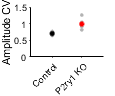

ylim([0 1.5])
xtickangle(45)

[~,p,ci,stats] = ttest2(CV,KOCV)

p = 3.7050e-05

ci =    -0.3889   -0.1822


stats = struct with fields:
    tstat: -5.9249
       df: 14
       sd: 0.0956


mean(CV)

ans = 0.7041

sterr(CV,2)

ans = 0.0126

mean(KOCV)

ans = 0.9896

sterr(KOCV,2)

ans = 0.0527

mean(KOCV)/mean(CV)

ans = 1.4055

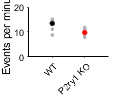

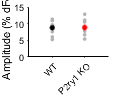

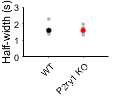

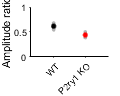

%plot all five
handleTheSubplot({h,h1,h2,h3,h4},[1 5]);

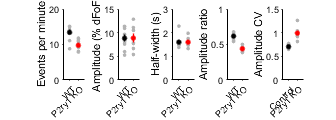

figQuality(gcf,gca,[3.5 1.25])
export_fig('.\EPS Panels\quant.eps')